% Apply edge detection methods
addpath('bresenham');

I = nextFrame;

SobelMask       = edge(I, 'Sobel');
PrewittMask     = edge(I, 'Prewitt');
RobertsMask     = edge(I, 'Roberts');
LoGMask         = edge(I, 'log');
ZeroCrossMask   = edge(I, 'zerocross');
CannyMask       = edge(I, 'Canny');
ApproxCannyMask = edge(I, 'approxcanny');

% % Plot the results
% figure;
% 
% subplot(3, 3, 1);
% imshow(I);
% title('Original Image');
% 
% subplot(3, 3, 2);
% imshow(SobelMask);
% title('Sobel');
% 
% subplot(3, 3, 3);
% imshow(PrewittMask);
% title('Prewitt');
% 
% subplot(3, 3, 4);
% imshow(RobertsMask);
% title('Roberts');
% 
% subplot(3, 3, 5);
% imshow(LoGMask);
% title('Laplacian of Gaussian (LoG)');
% 
% subplot(3, 3, 6);
% imshow(ZeroCrossMask);
% title('Zero Cross');
% 
% subplot(3, 3, 7);
% imshow(CannyMask);
% title('Canny');
% 
% subplot(3, 3, 8);
% imshow(ApproxCannyMask);
% title('Approx Canny');

total = SobelMask      | PrewittMask    | RobertsMask    | LoGMask        | ZeroCrossMask  | CannyMask      | ApproxCannyMask;



total = bwareaopen(total, 200, 4); % Remove small objects with fewer than 100 pixels
total = imclearborder(total, 8);

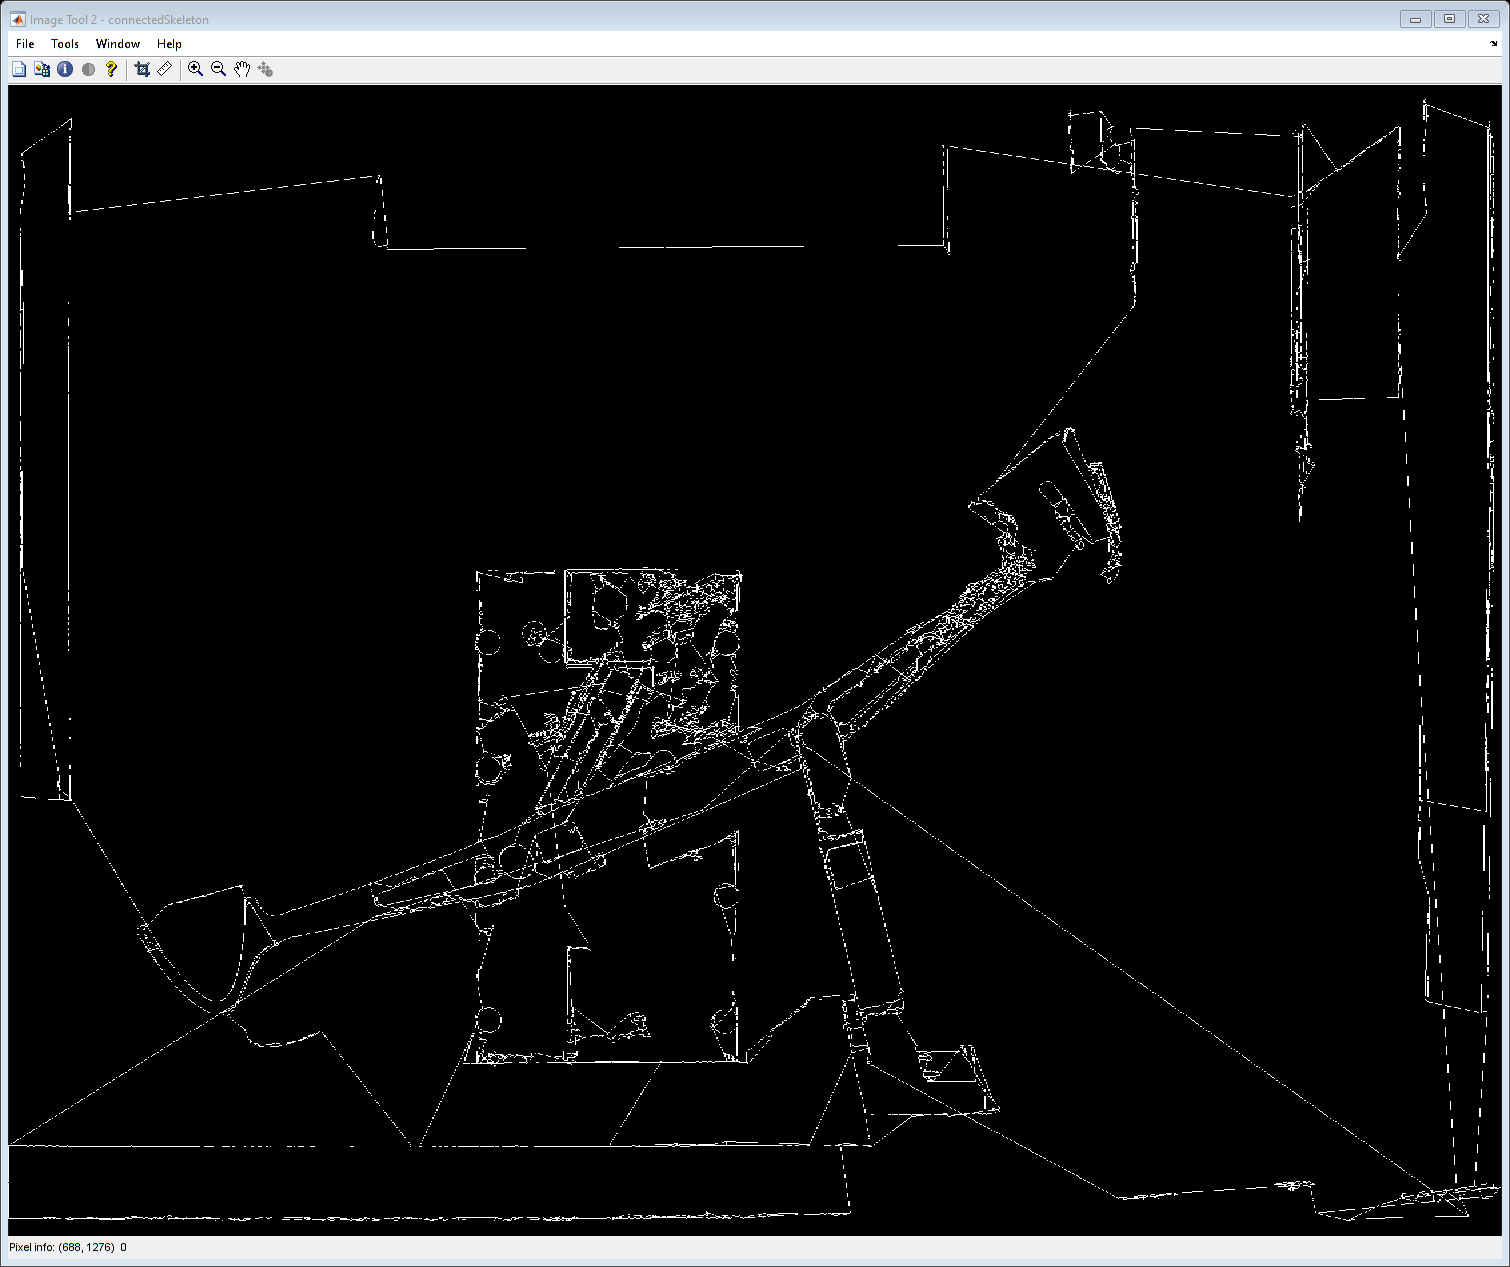


% Step 1: Skeletonize the binary image
skeleton = bwmorph(total, 'skel', Inf);

% Step 2: Detect endpoints
endpoints = bwmorph(skeleton, 'endpoints');


% Get coordinates of the endpoints
[end_y, end_x] = find(endpoints);

% Step 3: Connect spikes
% Create a copy of the skeleton for modifications

connectedSkeleton = connect_all_points(skeleton, end_x, end_y);

% Step 4: Visualize the results
imtool(connectedSkeleton);

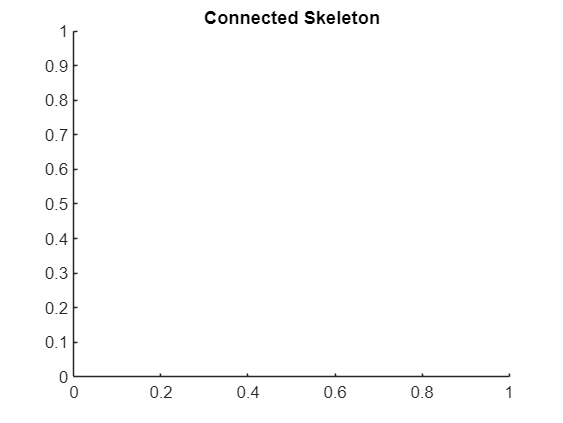

title('Connected Skeleton');


dilated = imdilate(connectedSkeleton, [1 1; 1 1]);

total = bwareaopen(~dilated, 50000, 4);

invertedMask = dilated | total;

mask = ~invertedMask

mask = 1726×2240 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

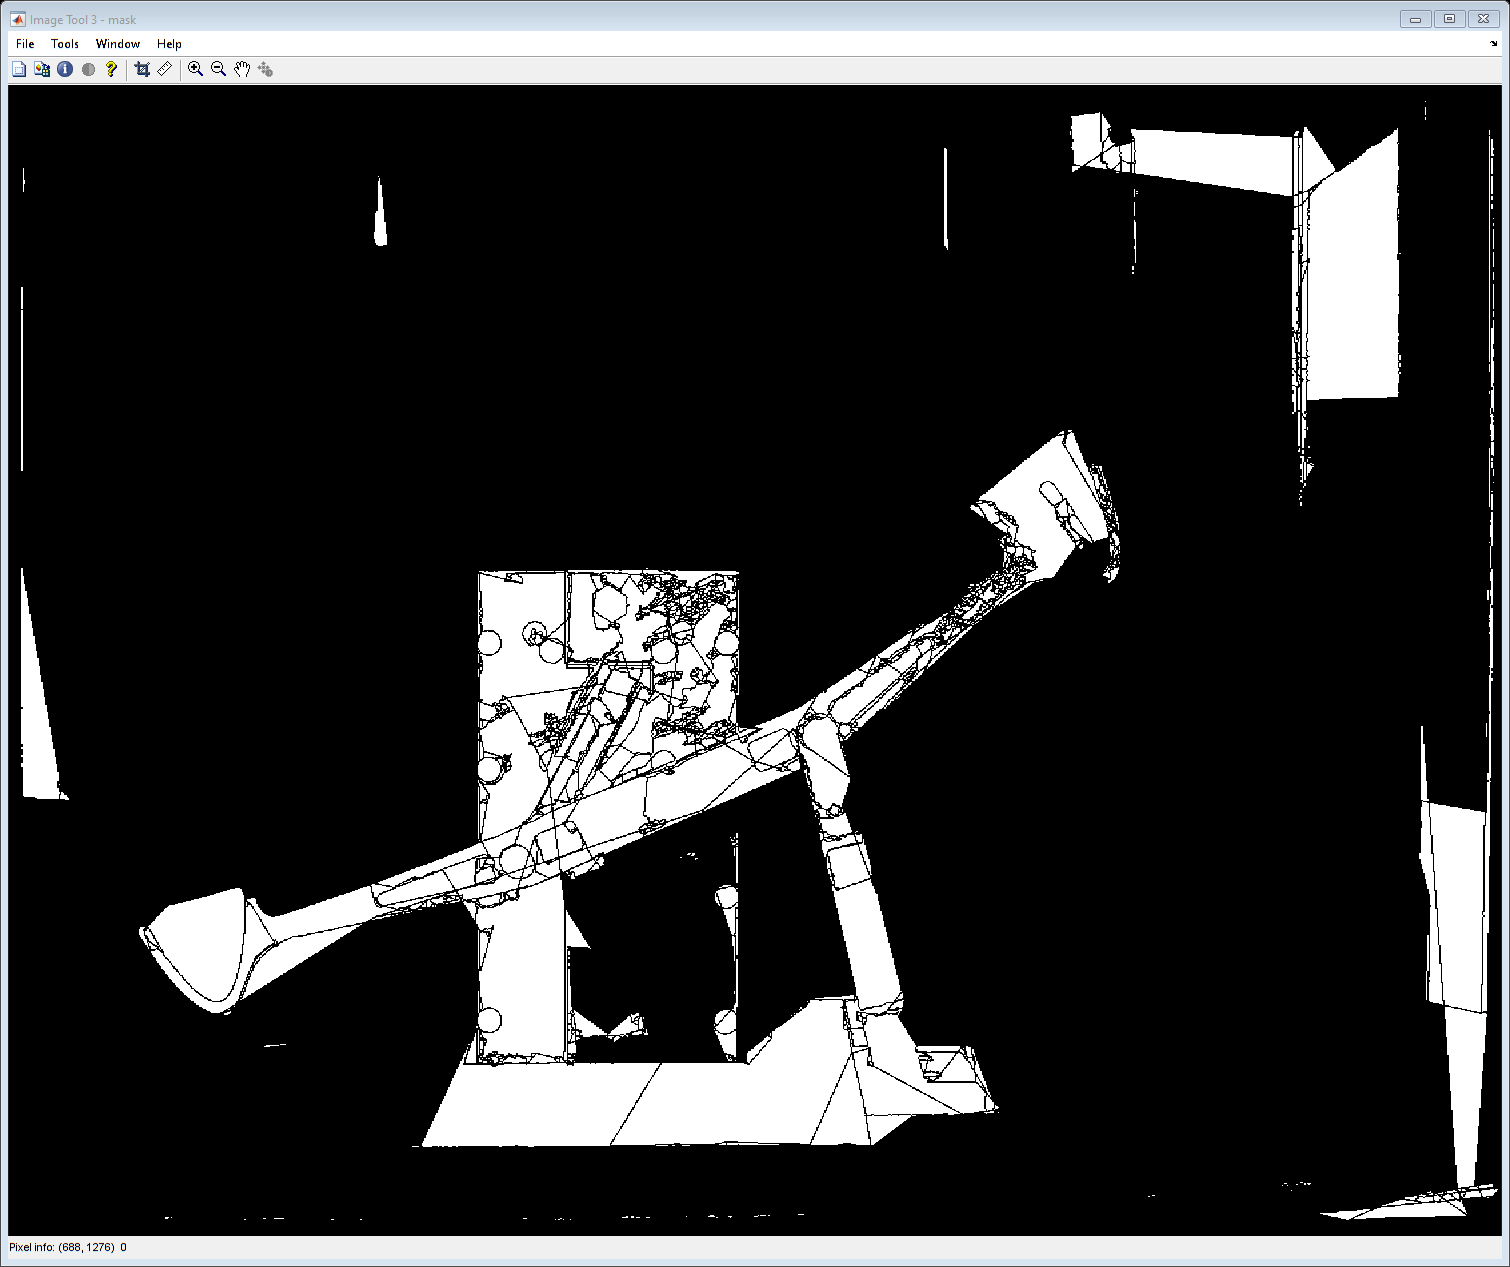


imtool(mask)



% Supporting Functions




% 
% % Combine edge detectors into a binary mask (already done in your setup)
% binaryMask = total; % Replace with your combined edge-detected binary mask
% 
% % Perform Hough Transform with finer angular resolution
% edges = binaryMask; % Use the combined binary mask directly
% [H, T, R] = hough(edges, 'Theta', -90:0.5:89.5); % Finer resolution
% 
% % Find peaks in the Hough transform
% peaks = houghpeaks(H, 1500, 'Threshold', ceil(0.01 * max(H(:)))); % Adjust as needed
% 
% % Extract lines using houghlines
% lines = houghlines(edges, T, R, peaks, 'FillGap', 3, 'MinLength', 50);
% 
% % Filter lines by length (keep lines > 40 pixels)
% longLines = [];
% for k = 1:length(lines)
%     % Compute length of the line
%     point1 = lines(k).point1;
%     point2 = lines(k).point2;
%     lineLength = sqrt((point2(1) - point1(1))^2 + (point2(2) - point1(2))^2);
%     if (lineLength > 40) & (lineLength < 200)
%         longLines = [longLines, lines(k)];
%     end
% end
% 
% % Plot the binary mask with filtered lines
% figure;
% imshow(binaryMask);
% hold on;
% 
% % Plot the detected long lines
% for k = 1:length(longLines)
%     point1 = longLines(k).point1;
%     point2 = longLines(k).point2;
%     plot([point1(1), point2(1)], [point1(2), point2(2)], 'LineWidth', 2, 'Color', 'green');
%     % Mark endpoints
%     plot(point1(1), point1(2), 'x', 'LineWidth', 2, 'Color', 'yellow');
%     plot(point2(1), point2(2), 'x', 'LineWidth', 2, 'Color', 'red');
% end
% hold off;


% 
% % Create a blank binary image to draw the extended lines
% extendedLinesImage = extendLinesUntilHit(binaryMask, lines, 1, 1);
% 
% % Combine the extended lines with the original binary mask
% resultMask = binaryMask | extendedLinesImage;
% 
% % Display results
% figure;
% subplot(1, 2, 1); imshow(extendedLinesImage); title('Extended Lines');
% subplot(1, 2, 2); imshow(resultMask); title('Combined Mask');
